addpath('C:\Users\filip\Desktop\investments_f\Functions') % path to get the functions for the models and the backtest function
addpath('C:\Users\filip\Desktop\investments_f\Datasets') % path to get datasets

clear
close
clc

% Inputs
load("Eurostoxx50.mat")
% Tickers = AssetPrices.Properties.VariableNames;
% Prices = table2array(AssetPrices);
R = diff(AssetPrices)./AssetPrices(1:end-1,:);
DL = 500;
DH = 20;

% Backtest
[Wealth_Ptf, R_Ptf_out, Weights] = F_Backtester_MaxArea(R,DL,DH);

% % Putting the index in the final Table
% IP = IndexPrice(end+1-size(Wealth_Ptf):end); % index price for the same days as the ptf
% IndexLevel = IP./IP(1);
% IndexLevel = table(IndexLevel);
% Wealth_Ptf = [Wealth_Ptf IndexLevel]; % insert in the final table also Index as the last column
% % Saving the Time of the whole strategy
% Time = Time(end-size(Wealth_Ptf,1)+1:end,:);

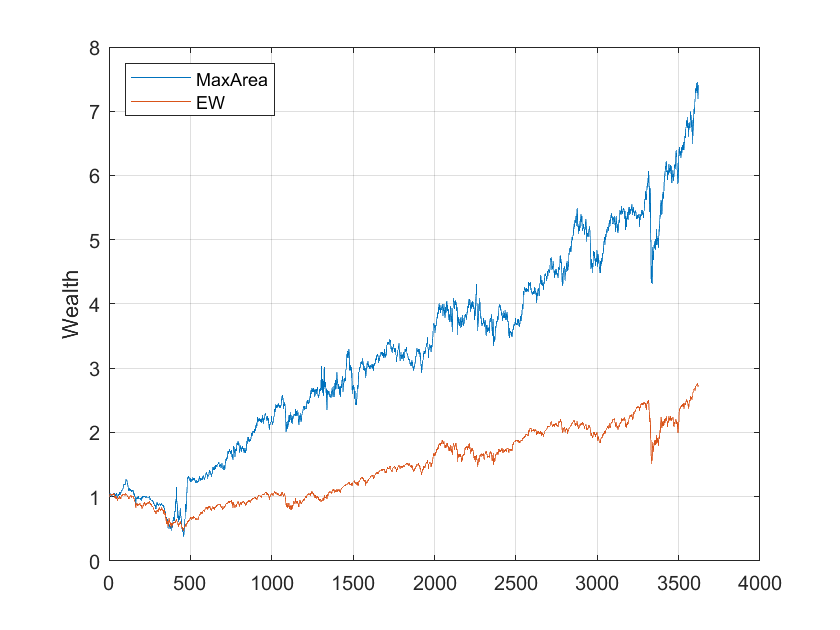

Model_Names = Wealth_Ptf.Properties.VariableNames;
Model_Names = regexprep(Model_Names, '_', ' ');
Wealth_to_plot = table2array(Wealth_Ptf);
figure
plot(Wealth_to_plot)
legend(Model_Names,'Location','northwest')
ylabel('Wealth')
grid

% Performance analysis
[Performance_Analysis] = F_Performance_Analysis(Wealth_Ptf)

% Saving output outside
save('Wealth_FTSE100','Wealth_Ptf')
save('R_Ptf_FTSE100','R_Ptf_out')
save('Weights_FTSE100','Weights')